# Sinusoid Motion of Chicken Analysis

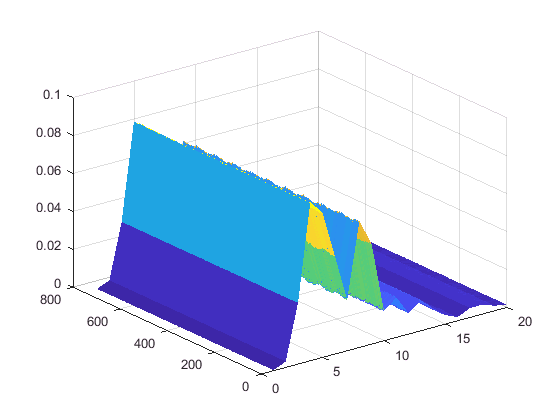

clc
clear
x = linspace(0.0, 9.9, 186);

% Filename
material = "chicken_water_5";
waveform = "sinusoid";
depth = "-1.5cm";
period = "5";
amplitude = "8";
trial = 1;

if (waveform == "sinusoid")
    filename = strcat(material, "/", waveform, "_D", depth, "_T", ...
        period, "_A", amplitude, "_", num2str(trial), ".mat");
end
if (waveform == "chirp")
    filename = strcat(material, "/", waveform, "_D", depth, "_A", amplitude, "_", num2str(trial), ".mat");
end
if (waveform == "patient")
    filename = strcat(material, "/", waveform, "_D", depth, ".mat");
end

%VariableName
dataType = "bb";
dacMIN = "0";
dacMAX = "1400";
frequency = "4";
varName = strcat(dataType, dacMIN, "_", dacMAX, "f", frequency);

clear amplitude dacMAX dacMIN dataType depth frequency material period trial waveform

load(filename, varName);
surf(abs(bb0_1400f4(:,1:20)), 'linestyle', 'none');